# **SISTEMAS DE CONTROL DISCRETO                                **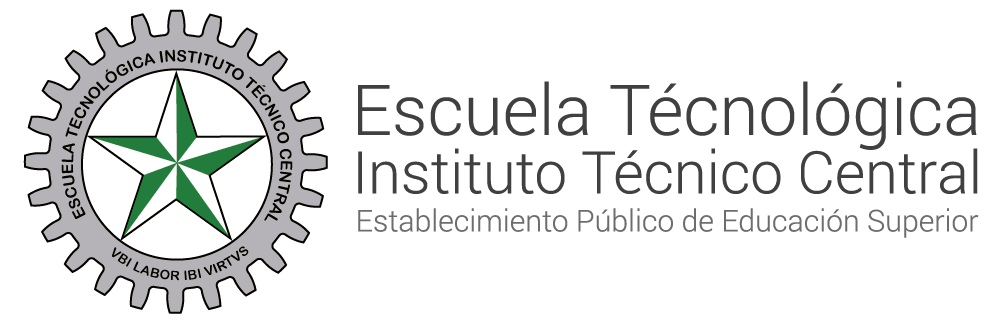

# **Función de Transferencia sistemas RLC **

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

#### Coautor: None

## OBJETIVO

Repasar los conceptos de sistemas dinámicos, sistemas de control y ecuaciones diferenciales.

## Ejercicio

Obtener la función de transferencia en el dominio de Laplace, en términos de R, L y C del siguiente sistema eléctrico:

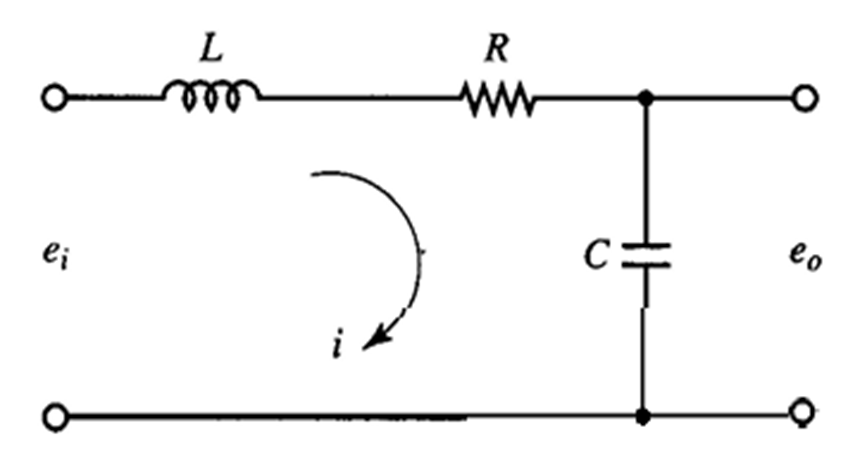

## Solución 

Por definición una función de transferencia esta dado por  la siguiente expresión:


$$H\left(S\right)=\frac{e_o }{e_i }$$


Se pueden usar como referencia la segunda ley de Kirchhoff:


$$\sum_{k=1}^n V_k =0$$


En donde $V_k$ es el voltaje en cada uno de los componentes del circuito. Por lo anterior el voltaje de $e_i$ se puede determinar de la siguiente manera:


$$\textrm{Vi}=e_i =V_L +V_R +V_C$$


Por otra parte, se puede observar que el voltaje de salida es el voltaje en el condensador, por lo que se puede asumir que:


$$e_o =V_C$$


Ahora con lo anterior, se procede a hallar la función de transferencia:


$$H=\frac{e_o }{e_i }=\frac{V_C }{V_L +V_R +V_C }$$


Sin embargo, es importante notar que las ecuaciones aún se encuentran en el dominio del tiempo. Para expreserar la función de transferencia de manera más útil en sistemas dinámicos, se debe aplicar la transformada de Laplace, lo que permite trabajar en el dominio de la frecuencia s:


$$H\left(s\right)=L\left(H\right)$$


En donde:


$$L\left\lbrace \textrm{VR}\right\rbrace =R$$


Siendo R una constante, la trasnformada de laplace de una constante se mantiene constante.


$$L\left\lbrace \textrm{VC}\right\rbrace =\frac{1}{\textrm{sC}}$$


Siendo el voltaje en C una derivada


$$L\left\lbrace \textrm{VL}\right\rbrace =\textrm{sL}$$


por lo que resulta: 


$$H\left(s\right)=\frac{e_o }{e_i }=\frac{\frac{1}{\textrm{sC}}}{\textrm{sL}+R+\frac{1}{\textrm{sC}}}$$


multiplicando el númerador y el denominador por $\textrm{sC}$ resulta la función de transferencia en terminos de la variable s:


$$H\left(s\right)=\frac{e_o }{e_i }=\frac{1}{\textrm{LC}s^2 +\textrm{CRs}+1}$$


Código Matlab

A continuación definimos las variables "symbolics" R, L, C y s para resolver el problema utilizando matlab.

syms R L C s 
V_R = R ;
V_L = L*s ;
V_C = 1/(C*s);

Definimos e_o


$$e_0 =V_c$$


e_o=V_C

$$e\_o = \frac{1}{C\,s}$$

Definimos e_i

e_i=V_L+V_R+V_C

$$e\_i = R+L\,s+\frac{1}{C\,s}$$

Finalmente definimos H

H = e_o/e_i;
simplify(H)

$$ans = \frac{1}{C\,L\,s^{2}+C\,R\,s+1}$$